# Ic/Io as a function of tension and torsion

Plots Ic/Io as a function of axial load, Fz (N), and twist, theta (radians/meter)

clc
clear
close all

## Inputs

% Tape specs
EConst = 148*10^9; %Tape elastic modulus at 77K in Pa from Zijia's thesis
SyConst = 850*10^6; %Tape yield strength at 77K in Pa from Zijia's thesis
eyConst = SyConst/EConst; %Tape strain at yield based on elastic modulus and yield strength
EtConst = 13*10^9; %Tape tangent modulus at 77K in Pa from Zijia's thesis

tConst = 0.092/2*10^-3; %1/2 tape thickness in m from Nate's thesis
wConst = 4.03/2*10^-3; %1/2 tape width in m from Nate's thesis

% Plot bounds
theta_min = 0;
theta_max = 90;
Fz_min = 0;
Fz_max = 300;

% Plot resolution
res = 40;

## Generate surface plot

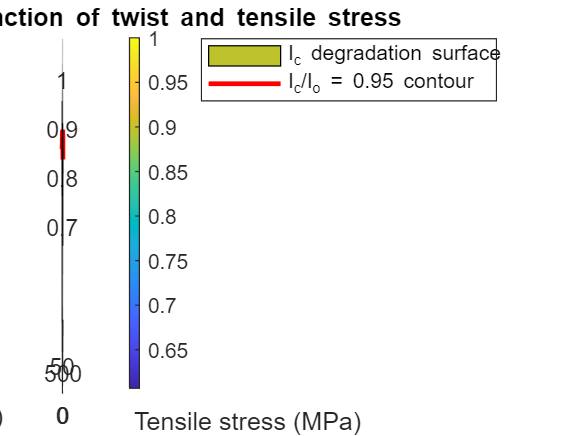

% Define the range of theta and Fz values
theta_vector = linspace(theta_min, theta_max, res);
Fz_vector = linspace(Fz_min, Fz_max, res);

% Create a grid of theta and Fz values
[theta_mesh, Fz_mesh] = meshgrid(theta_vector, Fz_vector);
Stress_mesh = Fz_mesh/(4*tConst*wConst*10^6);

% For loop to iterate through mesh and save degradation Ic/Io in the
IcIo_results = zeros(size(theta_mesh));

for i = 1:numel(theta_mesh)
    IcIo_results(i) = IcIo(theta_mesh(i), Fz_mesh(i), EConst, EtConst, SyConst, eyConst, wConst, tConst);
end
IcIo_results = reshape(IcIo_results, size(theta_mesh));

% Create the 3D surface plot
figure;
surf(Stress_mesh, theta_mesh, IcIo_results,"DisplayName",'I_c degradation surface');

% Add contour line for Ic/Io = 0.95
hold on;
contour3(Stress_mesh, theta_mesh, IcIo_results, [0.95 0.95], 'r', 'LineWidth', 2,'DisplayName','I_c/I_o = 0.95 contour');
ylabel('Theta (rad/m)');
xlabel('Tensile stress (MPa)');
zlabel('Normalized I_c');
title('Normalized I_c as a function of twist and tensile stress');
% subtitle('Bilinear Model');
colorbar
legend("Location","bestoutside")
hold off;